# Obstacle-Free Path Planning Using Hybrid A Star

Plan a collision-free path for a vehicle through a parking lot by using the Hybrid A* algorithm.

## Create and Assign Map to State Validator

Define the rows, columns and resoltution of the grid map.

rows = 10;
cols = 10;
resolution = 10;

Create a [binaryOccupancyMap](docid:nav_ref#bunq527) with cost values.

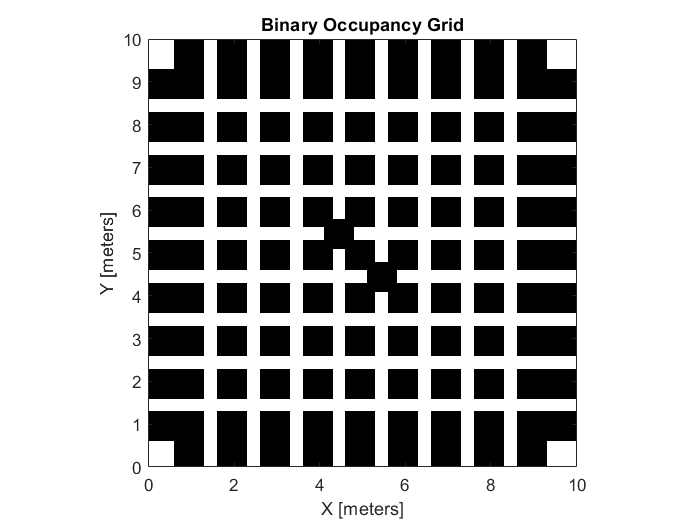

map = binaryOccupancyMap(rows,cols,resolution);

Obs = zeros([(rows-1)*(cols-1) 2]);

count = 1;

for x = 1 : rows-1
    for y = 1 : cols-1
        Obs(count,1) = x;
        Obs(count,2) = y;
        count = count + 1;
    end
end
setOccupancy(map, Obs, ones((rows-1)*(cols-1),1))

count = 1;
for x = 1 : rows-1
    Obs(count,1) = x;
    Obs(count,2) = 0+0.25;
    count = count + 1;
end
for x = 1 : rows-1
    Obs(count,1) = x;
    Obs(count,2) = cols-0.3;
    count = count + 1;
end
for y = 1 : cols-1
    Obs(count,1) = 0+0.25;
    Obs(count,2) = y;
    count = count + 1;
end
for y = 1 : cols-1
    Obs(count,1) = rows-0.3;
    Obs(count,2) = y;
    count = count + 1;
end
setOccupancy(map, Obs, ones((rows-1)*(cols-1),1))

setOccupancy(map, [5.5 4.5], 1)
setOccupancy(map, [4.5 5.5], 1)

%inflate(map,0.3)
squareInflate(map,3);

show(map)

Create a state validator object for collision checking.

validator = validatorOccupancyMap;

Assign the map to the state validator object.

validator.Map = map;

## Plan and Visualize Path

Initialize the [plannerHybridAStar](docid:nav_ref#object_plannerhybridastar) object with the state validator object. Specify the `MinTurningRadius` and `MotionPrimitiveLength` properties of the planner.

planner = plannerHybridAStar(validator,'MinTurningRadius',0.64,'MotionPrimitiveLength',0.5);

Define start and goal poses for the vehicle as [*x, y, theta*] vectors. *x* and *y* specify the position in meters, and *theta* specifies the orientation angle in radians.

startPose = [1.5 1.5 pi/2]; % [meters, meters, radians]
goalPose = [5.5 6.5 0];

Plan a path from the start pose to the goal pose.

refpath = plan(planner,startPose,goalPose);

Visualize the path using show function.

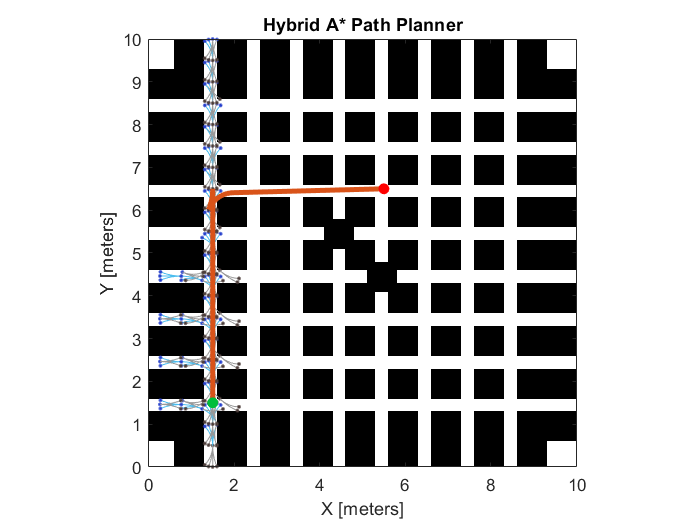

show(planner)

*Copyright 2019 The MathWorks, Inc.*